# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：      邓欣冉           学号：      24307026           专业：      电子信息工程         

## 实验六 模拟原型滤波器及IIR数字滤波器

## 一、实验目的

- 掌握模拟低通滤波器原型的设计方法

- 掌握模拟低通滤波器原型进行频率变换的方法

- 学习MATLAB模拟原型滤波器设计子函数的使用方法

- 掌握模拟滤波器原型进行脉冲响应变换的方法

- 掌握用双线性变换法设计IIR数字滤波器的方法

- 学习MATLAB直接设计IIR模拟滤波器和数字滤波器的方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

1、IIR 数字滤波器间接设计法整体流程

IIR 数字滤波器通常采用间接设计法实现，即先设计满足指标的模拟滤波器，再通过映射方法将其转换为数字滤波器。该方法充分利用了成熟的模拟滤波器设计理论，是工程中最常用的 IIR 滤波器设计方法。完整设计流程如下：

- 输入数字滤波器设计指标（通带 / 阻带截止频率、通带最大衰减\(R_p\)、阻带最小衰减\(A_s\)、采样频率\(F_s\)）

- 将数字频率指标转换为模拟频率指标（脉冲响应不变法采用线性映射，双线性变换法需进行频率预畸变）

- 计算模拟低通滤波器原型的最小阶数N和截止频率\(\Omega_c\)

- 设计模拟低通滤波器原型（本实验使用巴特沃斯和切比雪夫 I 型两种原型）

- 通过模拟域频率变换，将低通原型转换为实际所需的模拟滤波器（低通、高通、带通、带阻）

- 采用脉冲响应不变法或双线性变换法，将模拟滤波器数字化为数字滤波器

- 验证数字滤波器的频率特性是否满足设计要求

2、模拟低通滤波器原型设计

模拟低通滤波器原型是设计其他类型滤波器的基础，本实验主要使用巴特沃斯滤波器和切比雪夫I型滤波器

巴特沃斯滤波器的核心特点是通带和阻带内幅频特性单调下降，在 3dB 截止频率处衰减精确为 3dB。其平方幅度响应为：$\(|H_a(j\Omega)|^2 = \frac{1}{1+\left(\frac{\Omega}{\Omega_c}\right)^{2N}}\)$

切比雪夫 I 型滤波器的核心特点是通带内幅频特性等波纹波动，阻带内单调下降。在相同指标下，切比雪夫 I 型滤波器所需的阶数低于巴特沃斯滤波器，可有效降低系统复杂度。其平方幅度响应为：$\(|H_a(j\Omega)|^2 = \frac{1}{1+\varepsilon^2 C_N^2\left(\frac{\Omega}{\Omega_p}\right)}\)$

3、模拟域频率变换

通过频率变换可将归一化模拟低通原型滤波器转换为任意截止频率的低通、高通、带通、带阻滤波器，变换关系如下：

- 低通→低通：$\(s \to \frac{s}{\Omega_0}\)$，$\(\Omega_0\)$为目标低通滤波器的截止角频率

- 低通→高通：$\(s \to \frac{\Omega_0}{s}\)$，$\(\Omega_0\)$为目标高通滤波器的通带截止角频率

- 低通→带通：$\(s \to \frac{s^2+\Omega_0^2}{sB}\)$，$\(\Omega_0=\sqrt{\Omega_{p1}\Omega_{p2}}\)
$为中心角频率，$\(B=\Omega_{p2}-\Omega_{p1}\)为$通带带宽

- 低通→带阻：$\(s \to \frac{sB}{s^2+\Omega_0^2}\)$，$\(\Omega_0=\sqrt{\Omega_{s1}\Omega_{s2}}\)$为中心角频率，$\(B=\Omega_{s2}-\Omega_{s1}\)$为阻带带宽

4、模拟滤波器数字化方法

（1）脉冲响应不变法

脉冲响应不变法的核心思想是使数字滤波器的单位脉冲响应$\(h(n)\)$等于模拟滤波器单位冲激响应$\(h_a(t)\)$的采样值，即：


$$\(h(n) = h_a(nT)\)$$


其中T为采样周期。其 s 平面到 z 平面的映射关系为$\(z=e^{sT}\)$。

特点：

- 时域特性逼近好，适合对时域波形要求高的场景

- 存在频谱混叠现象，仅适用于带限的低通和带通滤波器，不适用于高通和带阻滤波器

- 模拟频率与数字频率呈线性关系：$\(\omega = \Omega T\)$

（2）双线性变换法

双线性变换法通过非线性频率压缩将整个 s 平面映射到 z 平面的单位圆内，映射关系为：


$$\(s = \frac{2}{T} \cdot \frac{1-z^{-1}}{1+z^{-1}}\)$$


特点：

- 彻底消除了频谱混叠现象，适用于所有类型的滤波器

- 会产生频率非线性畸变，因此需要在设计前对数字频率进行预畸变：$\(\Omega = \frac{2}{T} \tan\left(\frac{\omega}{2}\right)\)$

## 四、实验所用MATLAB函数

（列出实验中需要用到的MATLAB函数并简述其功能）

buttord(wp, ws, Rp, As, 's')：计算巴特沃斯滤波器的最小阶数和截止频率

cheb1ord(wp, ws, Rp, As, 's')：计算切比雪夫 I 型滤波器的最小阶数和截止频率

buttap(N)：设计 N 阶归一化巴特沃斯模拟低通原型

cheb1ap(N, Rp)：设计 N 阶归一化切比雪夫 I 型模拟低通原型

butter(N, Wn, 'ftype', 's')：设计巴特沃斯模拟 / 数字滤波器

cheby1(N, Rp, Wn, 'ftype', 's')：设计切比雪夫 I 型模拟 / 数字滤波器

lp2lp(b, a, W0)：低通→低通模拟滤波器变换

lp2hp(b, a, W0)：低通→高通模拟滤波器变换

lp2bp(b, a, W0, BW)：低通→带通模拟滤波器变换

lp2bs(b, a, W0, BW)：低通→带阻模拟滤波器变换

impinvar(b, a, Fs)：脉冲响应不变法转换模拟滤波器为数字滤波器

bilinear(num, den, Fs)：双线性变换法转换模拟滤波器为数字滤波器

freqs(B, A, w)：计算模拟滤波器的频率响应

freqz(b, a, n, Fs)：计算数字滤波器的频率响应

zplane(b, a)：绘制数字滤波器的零极点分布图

tf2zp(B, A)：将传递函数形式转换为零极点增益形式

poly(p)：将零极点转换为多项式系数

unwrap(phase)：展开相位响应，消除 2π 跳变

## 五、实验内容、方法、代码与结果

### **题目1**：设计一个*模拟低通滤波器*，通带截止频率$f_p=6kHz$，通带最大衰减$R_p\le1dB$，阻带截止频率$f_s=15kHz$，阻带最小衰减$A_s\ge30dB$。要求：

### （1）请用解析法（根据教材上例6.2.1的求解过程）实现巴特沃斯滤波器的设计，并分别用阻带条件求解和通带条件求解Ωc，得到两个模拟滤波器。在一张图同时画出两个滤波器的幅频特性（先除以最大值归一化，再取dB）。观察两个滤波器的3dB截止频率Ωc，并给出结论，那种求解方式的Ωc更大。

### （2）matlab库函数法实现巴特沃斯低通滤波器的设计，绘制幅频特性（归一化取dB）和相频特性曲线、零极点分布图，并列写出传递函数表达式。

**解答1**：

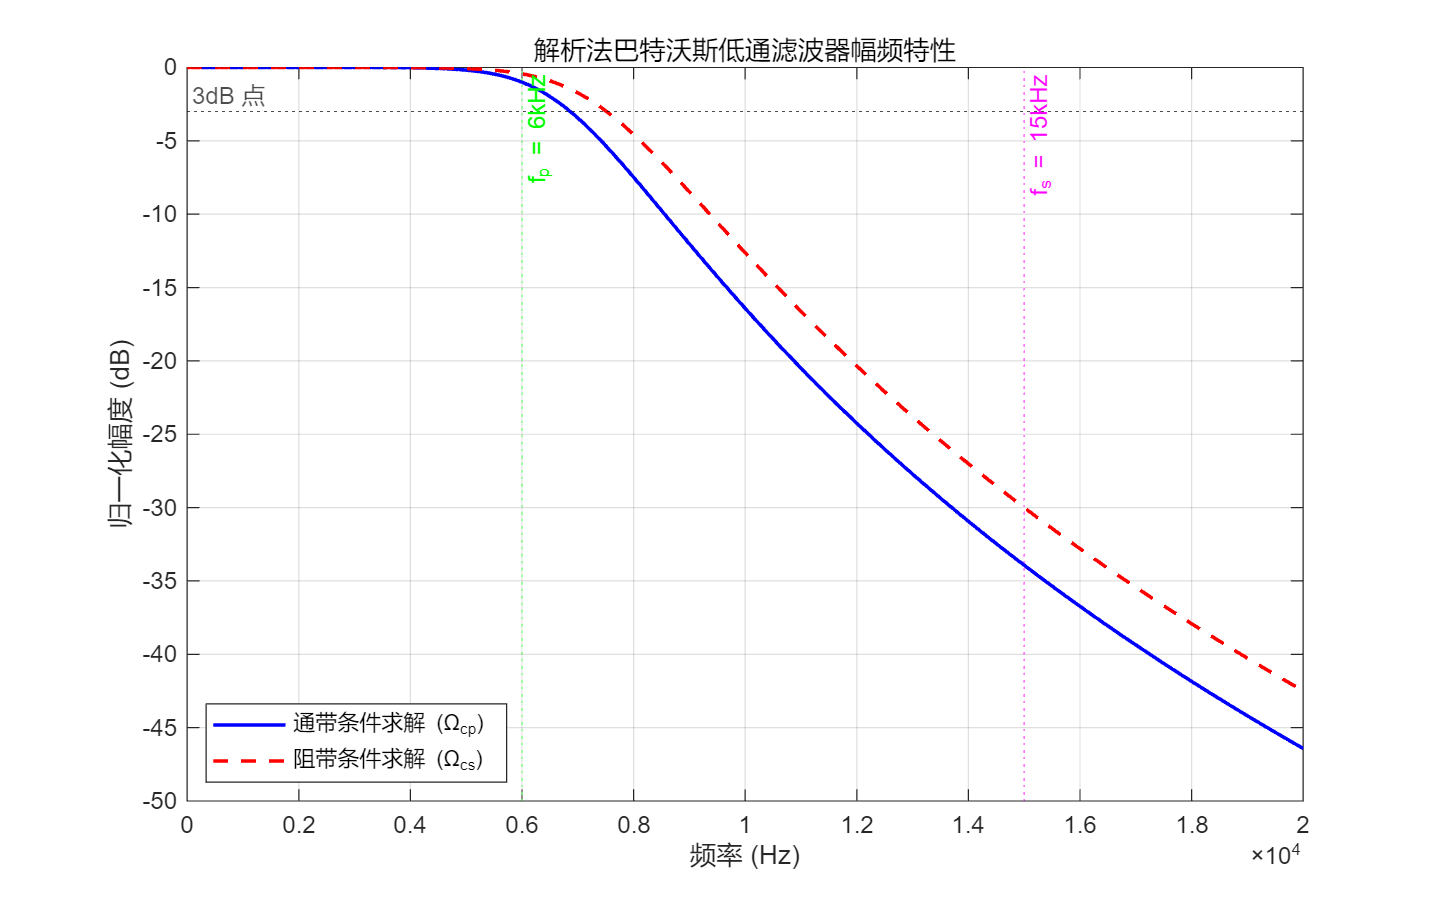

% Insert your code here
clear; clc;
fp = 6000;
fs = 15000;
Rp = 1;
As = 30;

%% 解析法求解
Op = 2 * pi * fp;
Os = 2 * pi * fs;

num = 10^(0.1 * As) - 1;
den = 10^(0.1 * Rp) - 1;
N_exact = log10(sqrt(num/den)) / log10(Os/Op);
N = ceil(N_exact); % 向上取整

Oc_p = Op / (den^(1/(2*N))); % 通带条件求得的 Ωc
Oc_s = Os / (num^(1/(2*N))); % 阻带条件求得的 Ωc

[Bp, Ap] = butter(N, Oc_p, 's'); % 基于通带条件的滤波器
[Bs, As_den] = butter(N, Oc_s, 's'); % 基于阻带条件的滤波器

f_vec = linspace(0, 20000, 1000); % 频率0~20kHz
w_vec = 2 * pi * f_vec;

Hp = freqs(Bp, Ap, w_vec);
Hs = freqs(Bs, As_den, w_vec);

% 归一化并取 dB
mag_p_dB = 20 * log10(abs(Hp) / max(abs(Hp)));
mag_s_dB = 20 * log10(abs(Hs) / max(abs(Hs)));

figure('Name', '解析法：不同条件求得的滤波器对比', 'Position', [100, 100, 800, 500]);
plot(f_vec, mag_p_dB, 'b', 'LineWidth', 1.5); 
hold on;
plot(f_vec, mag_s_dB, 'r--', 'LineWidth', 1.5);
yline(-3, 'k:', '3dB 点', 'LabelHorizontalAlignment', 'left');
xline(fp, 'g:', 'f_p = 6kHz');
xline(fs, 'm:', 'f_s = 15kHz');
xlabel('频率 (Hz)');
ylabel('归一化幅度 (dB)');
title('解析法巴特沃斯低通滤波器幅频特性');
legend('通带条件求解 (\Omega_{cp})', '阻带条件求解 (\Omega_{cs})', 'Location', 'southwest');
grid on;

disp('由图可得：阻带条件曲线与-3dB虚线交点位置的横坐标更大，所以阻带条件求解的Ωc更大')

由图可得：阻带条件曲线与-3dB虚线交点位置的横坐标更大，所以阻带条件求解的Ωc更大


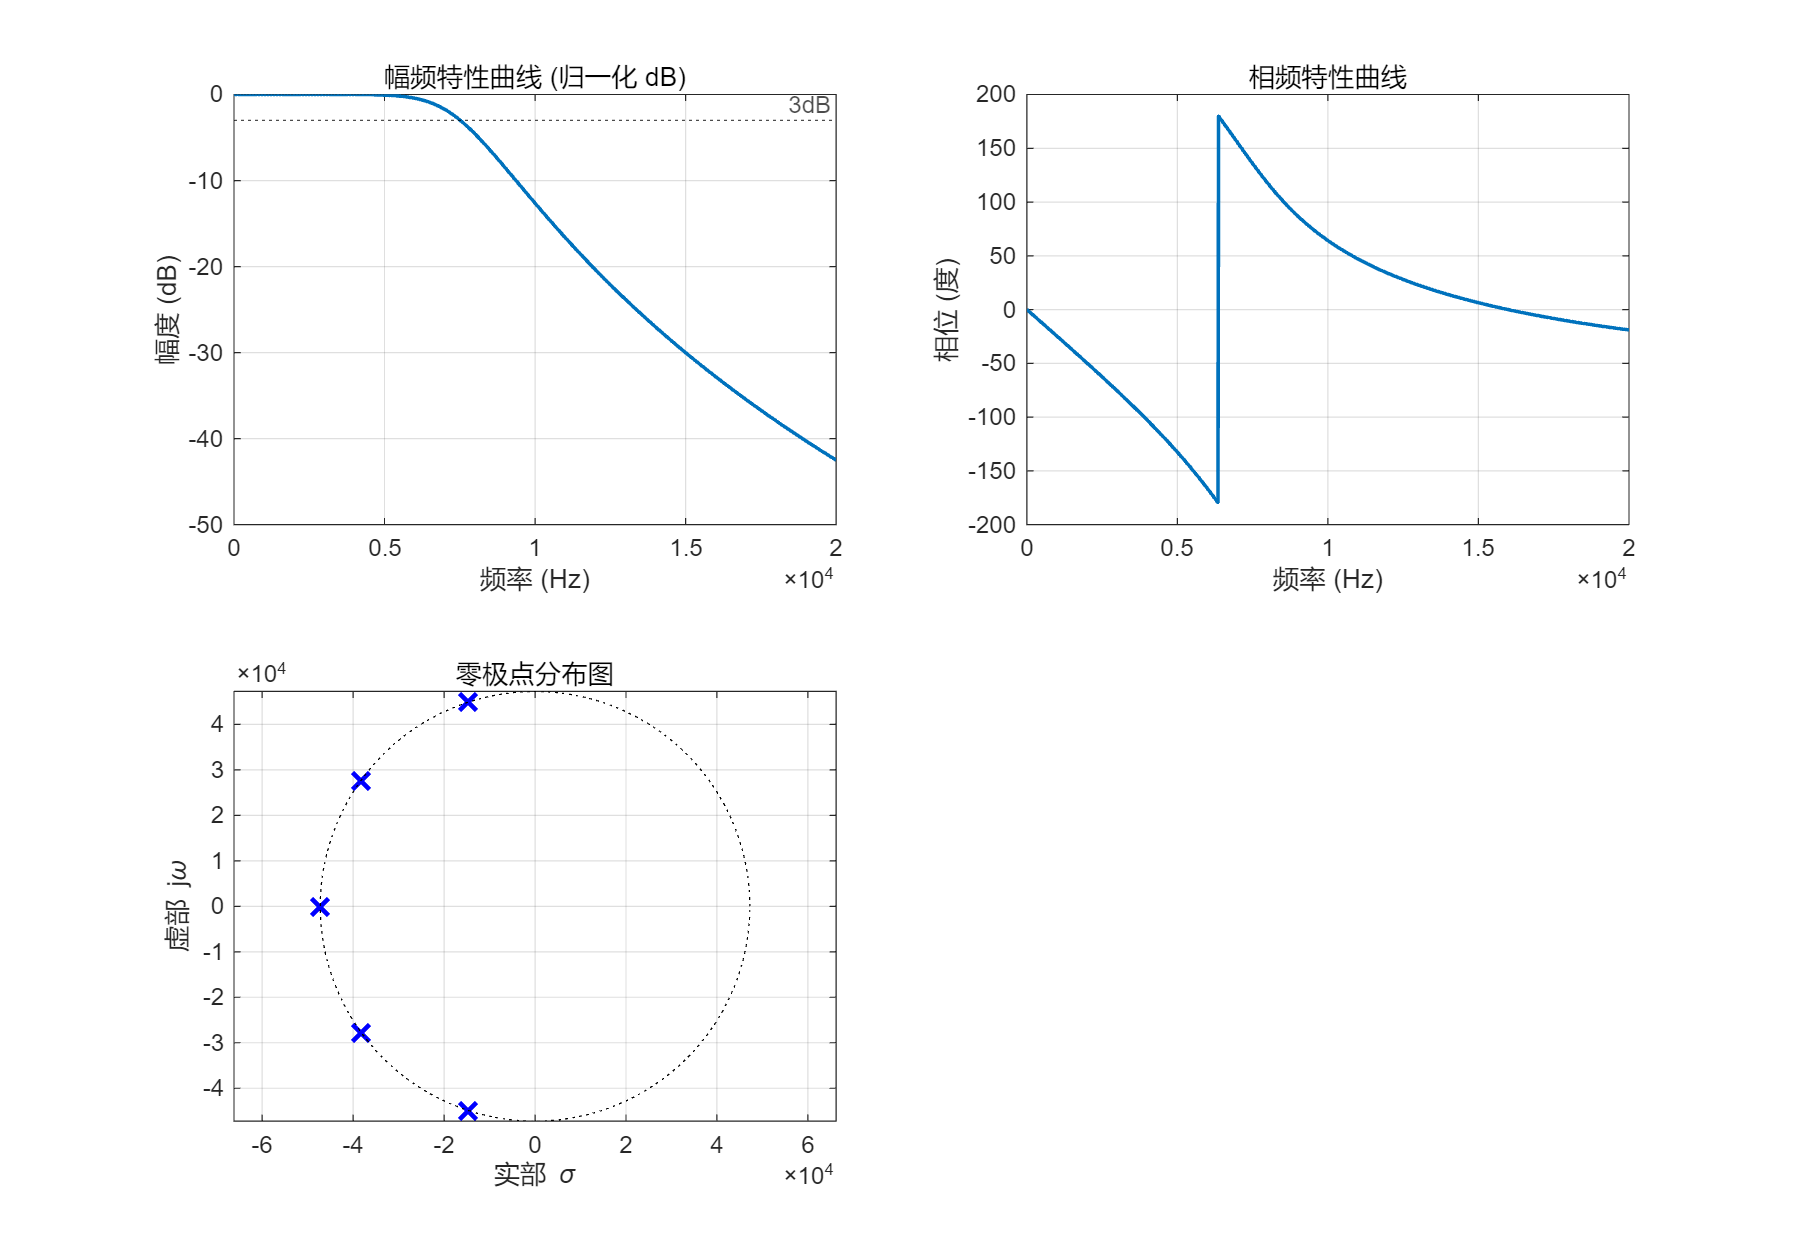


%% MATLAB 库函数法求解

[N_mat, Oc_mat] = buttord(Op, Os, Rp, As, 's');

% 使用 butter 设计滤波器
[B, A] = butter(N_mat, Oc_mat, 's');

figure('Name', '库函数法：滤波器全面特性', 'Position', [150, 150, 1000, 700]);
H_mat = freqs(B, A, w_vec);
mag_mat_dB = 20 * log10(abs(H_mat) / max(abs(H_mat)));
phase_mat = angle(H_mat) * 180 / pi; % 转换为角度

subplot(2, 2, 1);
plot(f_vec, mag_mat_dB, 'LineWidth', 1.5);
yline(-3, 'k:', '3dB');
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
title('幅频特性曲线 (归一化 dB)');
grid on;

% 相频特性
subplot(2, 2, 2);
plot(f_vec, phase_mat, 'LineWidth', 1.5);
xlabel('频率 (Hz)'); ylabel('相位 (度)');
title('相频特性曲线');
grid on;

% 零极点分布图
subplot(2, 2, 3);
[z, p, k] = tf2zp(B, A); % 
plot(real(p), imag(p), 'bx', 'MarkerSize', 10, 'LineWidth', 2); hold on;
if ~isempty(z)
    plot(real(z), imag(z), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
end

theta = linspace(0, 2*pi, 100);
plot(Oc_mat * cos(theta), Oc_mat * sin(theta), 'k:');
xlabel('实部 \sigma'); ylabel('虚部 j\omega');
title('零极点分布图');
axis equal; grid on;


disp('MATLAB 库函数法设计得到的传递函数 H(s) 为：');

MATLAB 库函数法设计得到的传递函数 H(s) 为：



$$H(s) = \frac{2.3527 \times 10^{23}}{s^5 + 1.5287 \times 10^5 s^4 + 1.1685 \times 10^{10} s^3 + 5.5201 \times 10^{14} s^2 + 1.6117 \times 10^{19} s + 2.3527 \times 10^{23}}$$


### **题目2**：用库函数法设计一个*切比雪夫Ⅰ型模拟低通滤波器*，要求通带截止频率$f_p=3.5kHz$，通带最大衰减$R_p\le1dB$，阻带截止频率$f_s=6kHz$，阻带最小衰减$A_s\ge40dB$。绘制归一化的模拟滤波器原型和实际模拟低通滤波器的频率特性。

**解答2**：

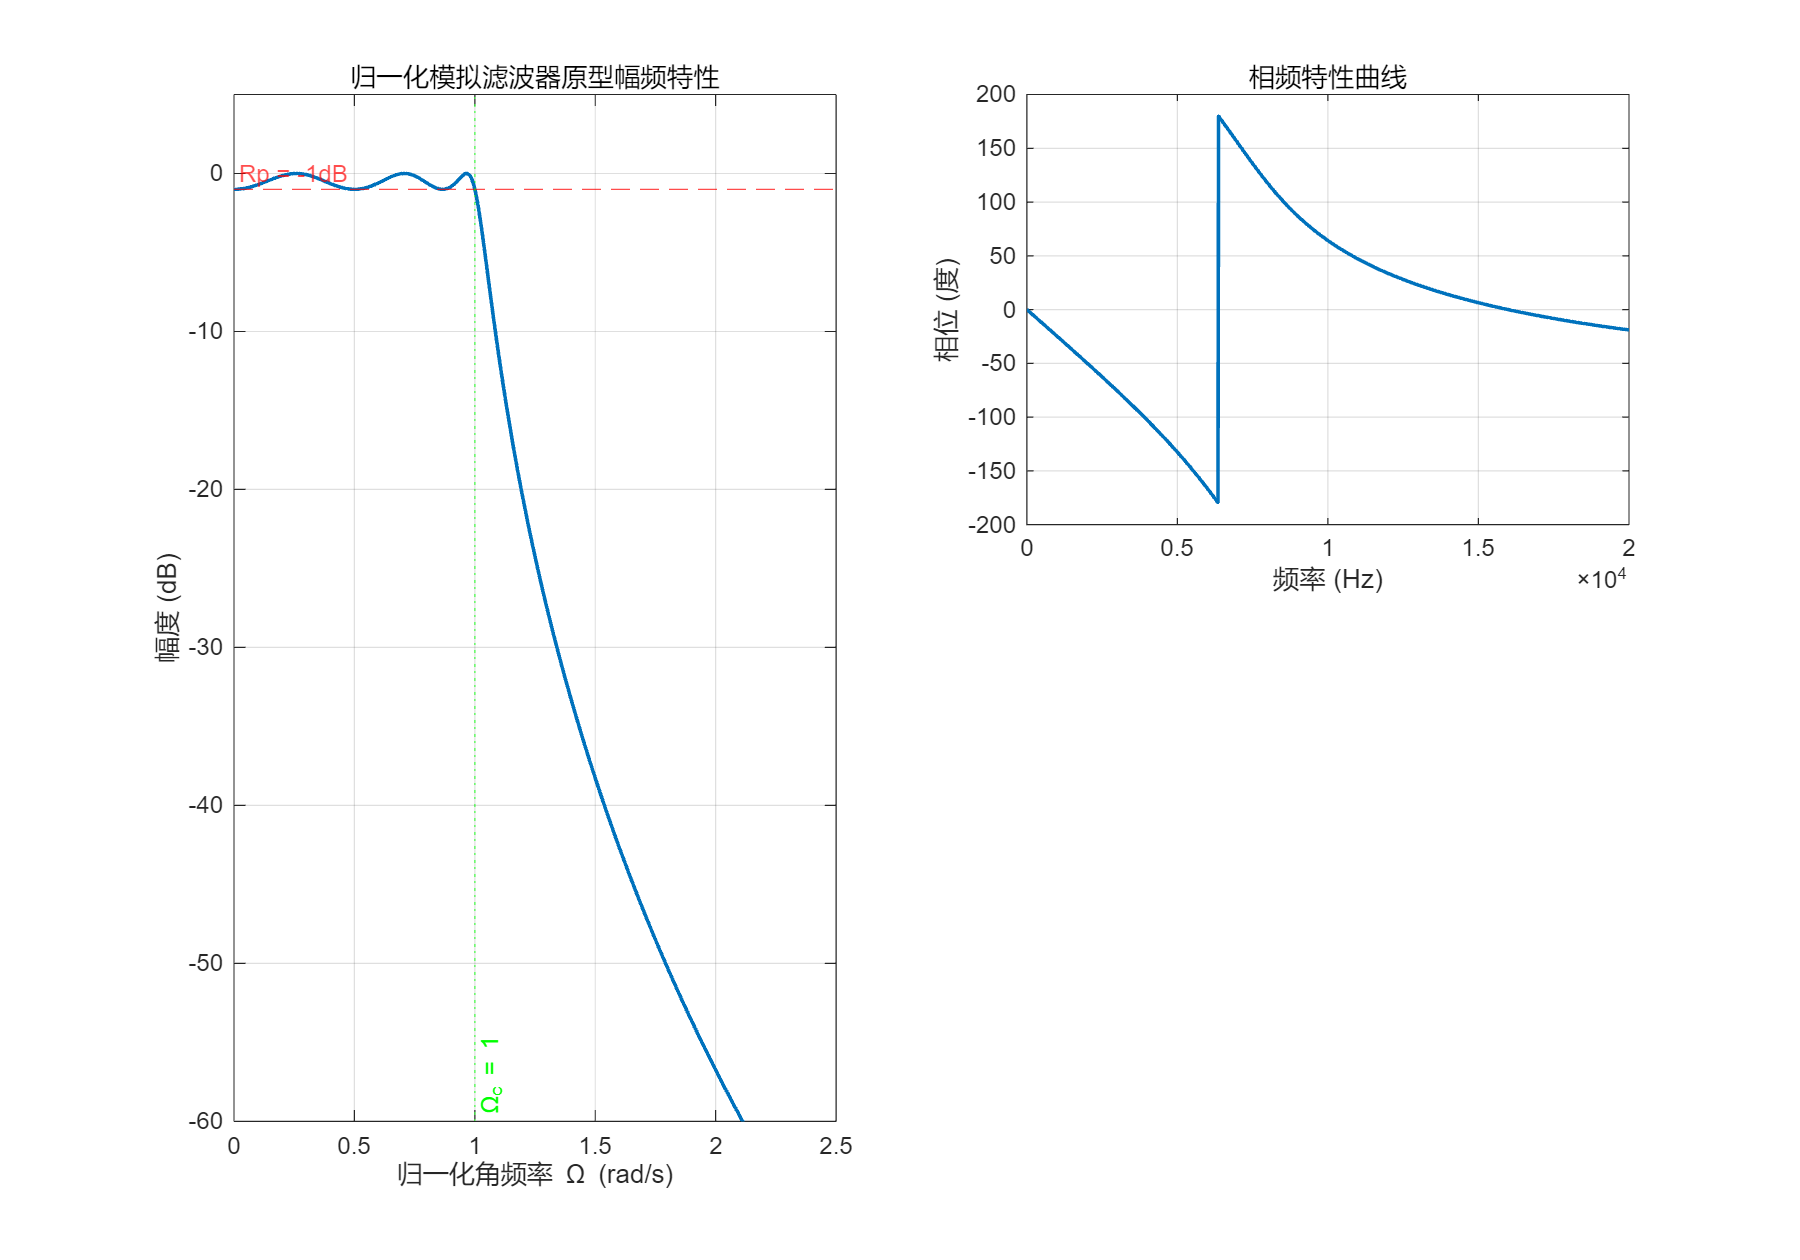

% Insert your code here
clear; clc;
fp = 3500;
fs = 6000;
Rp = 1;
As = 40;

Op = 2 * pi * fp;
Os = 2 * pi * fs;

num = 10^(0.1 * As) - 1;
den = 10^(0.1 * Rp) - 1;
N_exact = log10(sqrt(num/den)) / log10(Os/Op);
N = ceil(N_exact); 

[N, Wn] = cheb1ord(Op, Os, Rp, As, 's');
[b_norm, a_norm] = cheby1(N, Rp, 1, 's');
[b_real, a_real] = cheby1(N, Rp, Wn, 's');

subplot(1, 2, 1);
w_norm = linspace(0, 3, 1000); 
H_norm = freqs(b_norm, a_norm, w_norm);
mag_norm_dB = 20 * log10(abs(H_norm));

plot(w_norm, mag_norm_dB, 'LineWidth', 1.5);
ylim([-60, 5]);
yline(-Rp, 'r--', 'Rp = -1dB', 'LabelHorizontalAlignment', 'left');
xline(1, 'g:', '\Omega_c = 1', 'LabelVerticalAlignment', 'bottom');
title('归一化模拟滤波器原型幅频特性');
xlabel('归一化角频率 \Omega (rad/s)');
ylabel('幅度 (dB)');
grid on;

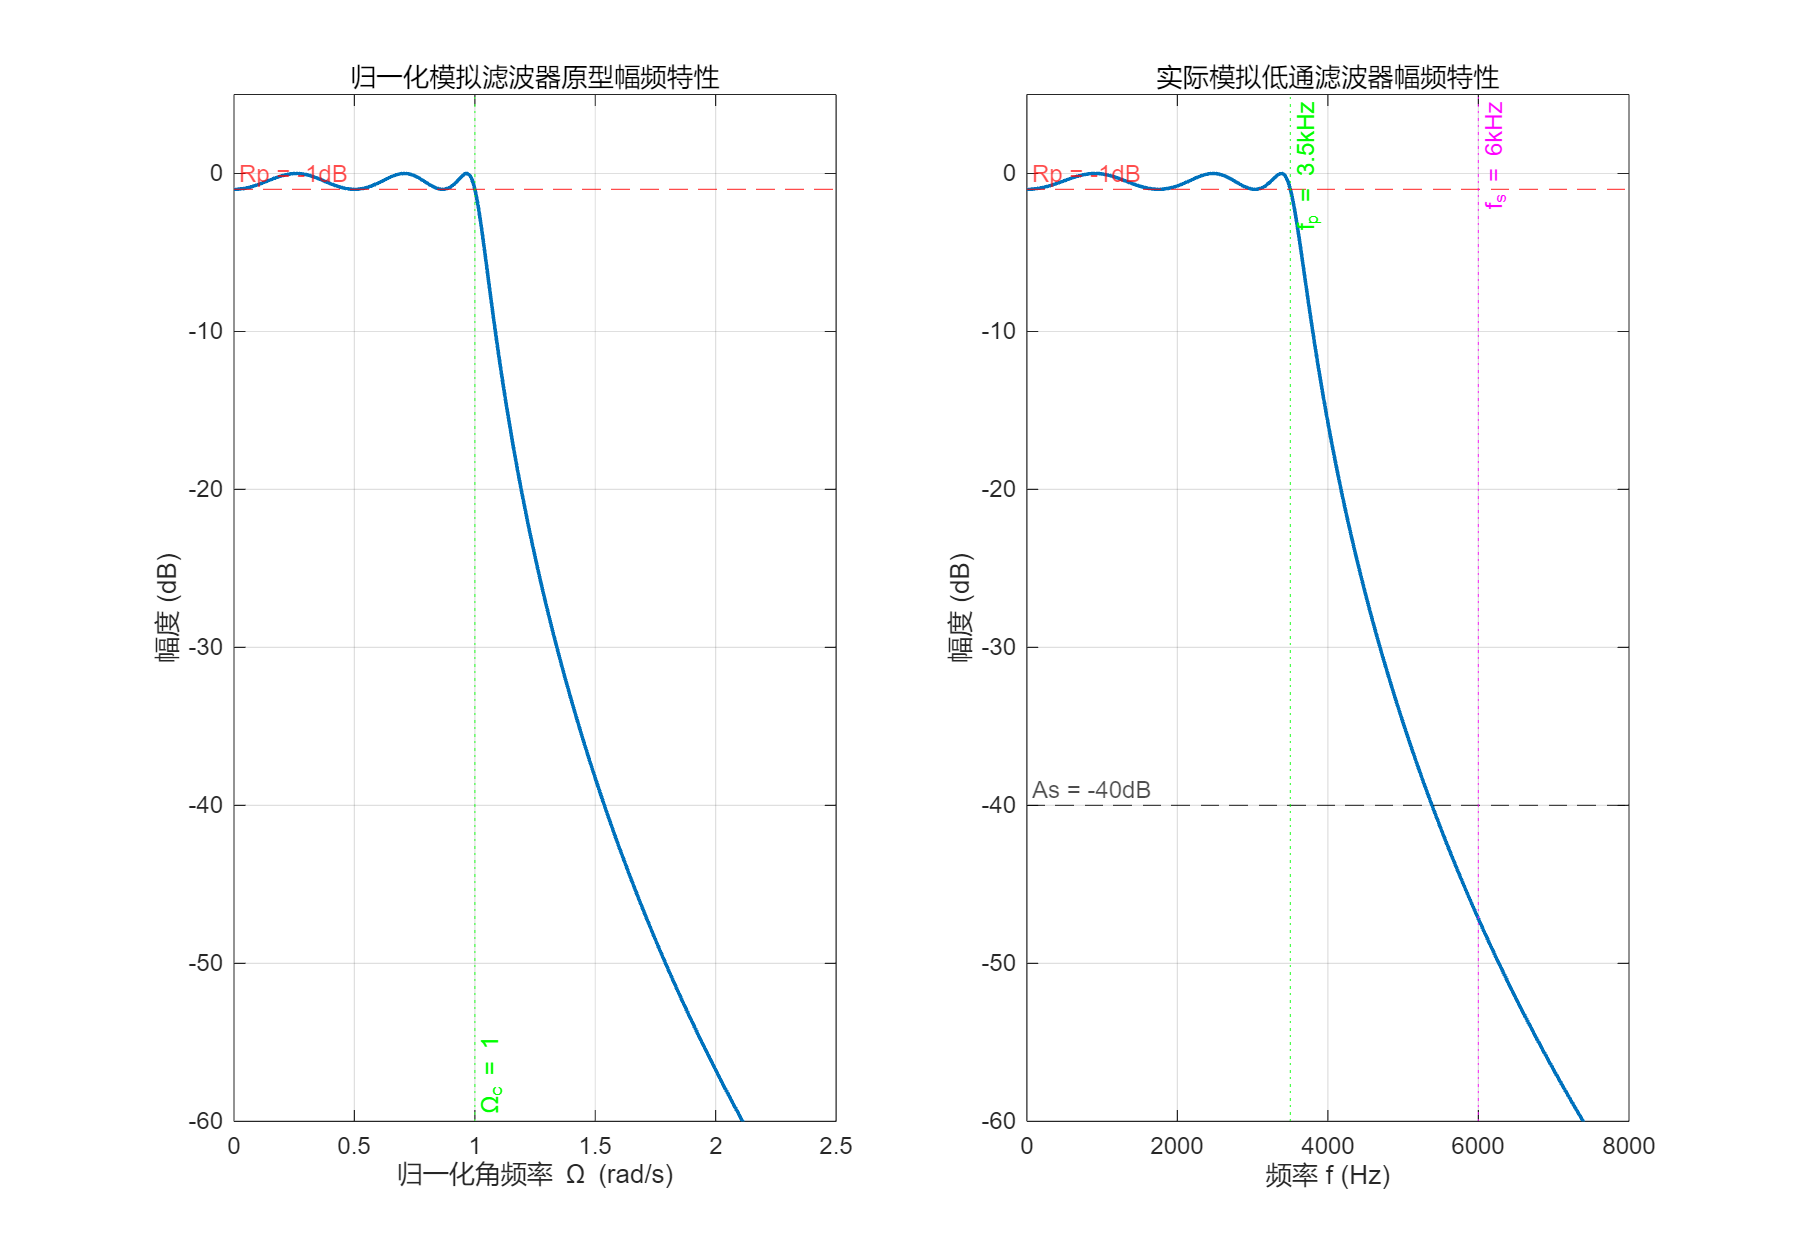


subplot(1, 2, 2);
f_vec = linspace(0, 10000, 1000); % 实际频率范围设为 0~10kHz
w_real = 2 * pi * f_vec;
H_real = freqs(b_real, a_real, w_real);
mag_real_dB = 20 * log10(abs(H_real));

plot(f_vec, mag_real_dB, 'LineWidth', 1.5);
ylim([-60, 5]);
yline(-Rp, 'r--', 'Rp = -1dB', 'LabelHorizontalAlignment', 'left');
yline(-As, 'k--', 'As = -40dB', 'LabelHorizontalAlignment', 'left');
xline(fp, 'g:', 'f_p = 3.5kHz');
xline(fs, 'm:', 'f_s = 6kHz');
title('实际模拟低通滤波器幅频特性');
xlabel('频率 f (Hz)');
ylabel('幅度 (dB)');
grid on;

### **题目3**：采用*双线性变换法*设计一个巴特沃斯*数字高通滤波器*，要求通带$f_{p}=300Hz,R_p=1dB$；阻带$f_{s1}=150Hz,A_s=20dB$，滤波器采样频率$F_s=1000Hz$。采用解析法求解，按照数字高通——>模拟高通——>模拟低通原型——>设计模拟低通原型——>模拟高通——>数字高通的方法来设计，不要用库函数。

**解答3**：

% Insert your code here
clear; clc;
fp = 300;
fs = 150;
Rp = 1;
As = 20;
Fs = 1000;
T = 1/ Fs;

%% 解析法求解
wp = 2 * pi * fp / Fs;
ws = 2 * pi * fs / Fs;

c = 2/T;
Op = 2/T * tan(wp/2);
Os = 2/T * tan(ws/2);

lambda_p = 1;          
lambda_s = Op / Os;

num = 10^(0.1 * As) - 1;
den = 10^(0.1 * Rp) - 1;
N_exact = log10(sqrt(num/den)) / log10(lambda_s/lambda_p);
N = ceil(N_exact);

lambda_c = lambda_p / (den^(1/(2*N)));
k = 1:N;
p_lp = lambda_c * exp(1j * pi * (2*k + N - 1) / (2*N));

p_hp = Op ./ p_lp;    %计算模拟高通极点
% 计算数字极点：
z_p = (c + p_hp) ./ (c - p_hp);
% 计算数字零点：模拟高通原点的零点映射到 z 域的 z=1 处
z_z = ones(1, N);
% 计算传递增益 K：
K = real( (c^N) / prod(c - p_hp) );

% 利用 poly 函数将零极点展开为分子分母多项式系数
b = K * poly(z_z);
a = real(poly(z_p));  % 取实部
fprintf('计算得滤波器阶数 N = %d\n\n', N);

计算得滤波器阶数 N = 3



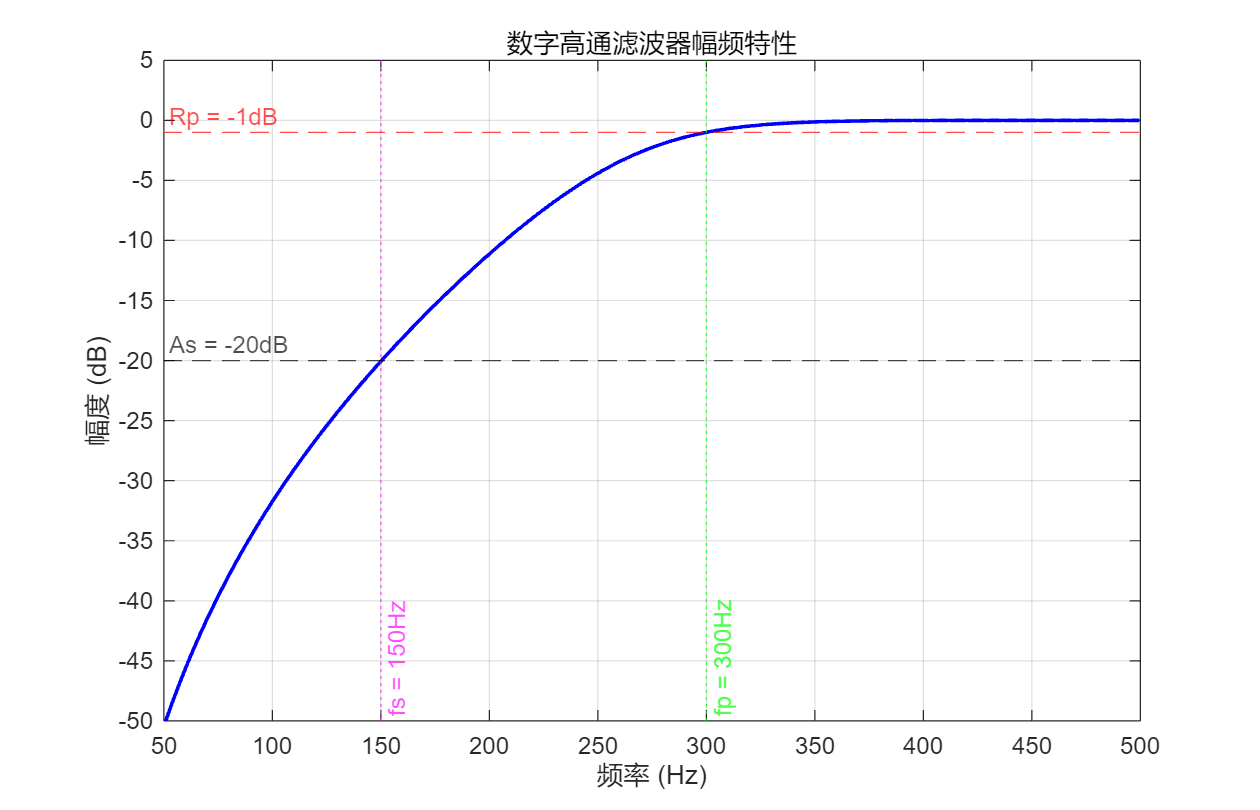

figure('Name', '解析法双线性变换设计数字高通滤波器', 'Position', [200, 200, 700, 450]);
[H, f] = freqz(b, a, 1024, Fs);
mag_dB = 20 * log10(abs(H));

plot(f, mag_dB, 'b', 'LineWidth', 1.5); hold on;
yline(-Rp, 'r--', 'Rp = -1dB', 'LabelHorizontalAlignment', 'left');
yline(-As, 'k--', 'As = -20dB', 'LabelHorizontalAlignment', 'left');
xline(fp, 'g:', 'fp = 300Hz', 'LabelVerticalAlignment', 'bottom');
xline(fs, 'm:', 'fs = 150Hz', 'LabelVerticalAlignment', 'bottom');
ylim([-50, 5]);
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
title('数字高通滤波器幅频特性');
grid on;

**该数字高通滤波器传递函数为：**$H(z) = \frac{0.1441 - 0.4323 z^{-1} + 0.4323 z^{-2} - 0.1441 z^{-3}}{1 + 0.1726 z^{-1} + 0.3412 z^{-2} + 0.0158 z^{-3}}$

### **题目4**：用*MATLAB库函数法*设计*切比雪夫Ⅰ型数字带阻滤波器*，要求：$f_{p1}=1kHz,f_{p2}=4.5kHz,R_p=1dB$；阻带$f_{s1}=2kHz,f_{s2}=3.5kHz,A_s=20dB$，滤波器采样频率$F_s=10kHz$。请描绘滤波器绝对和相对幅频特性、相频特性、零极点分布图，列出系统传递函数式(程序后已经给出模板)。

**解答4**：

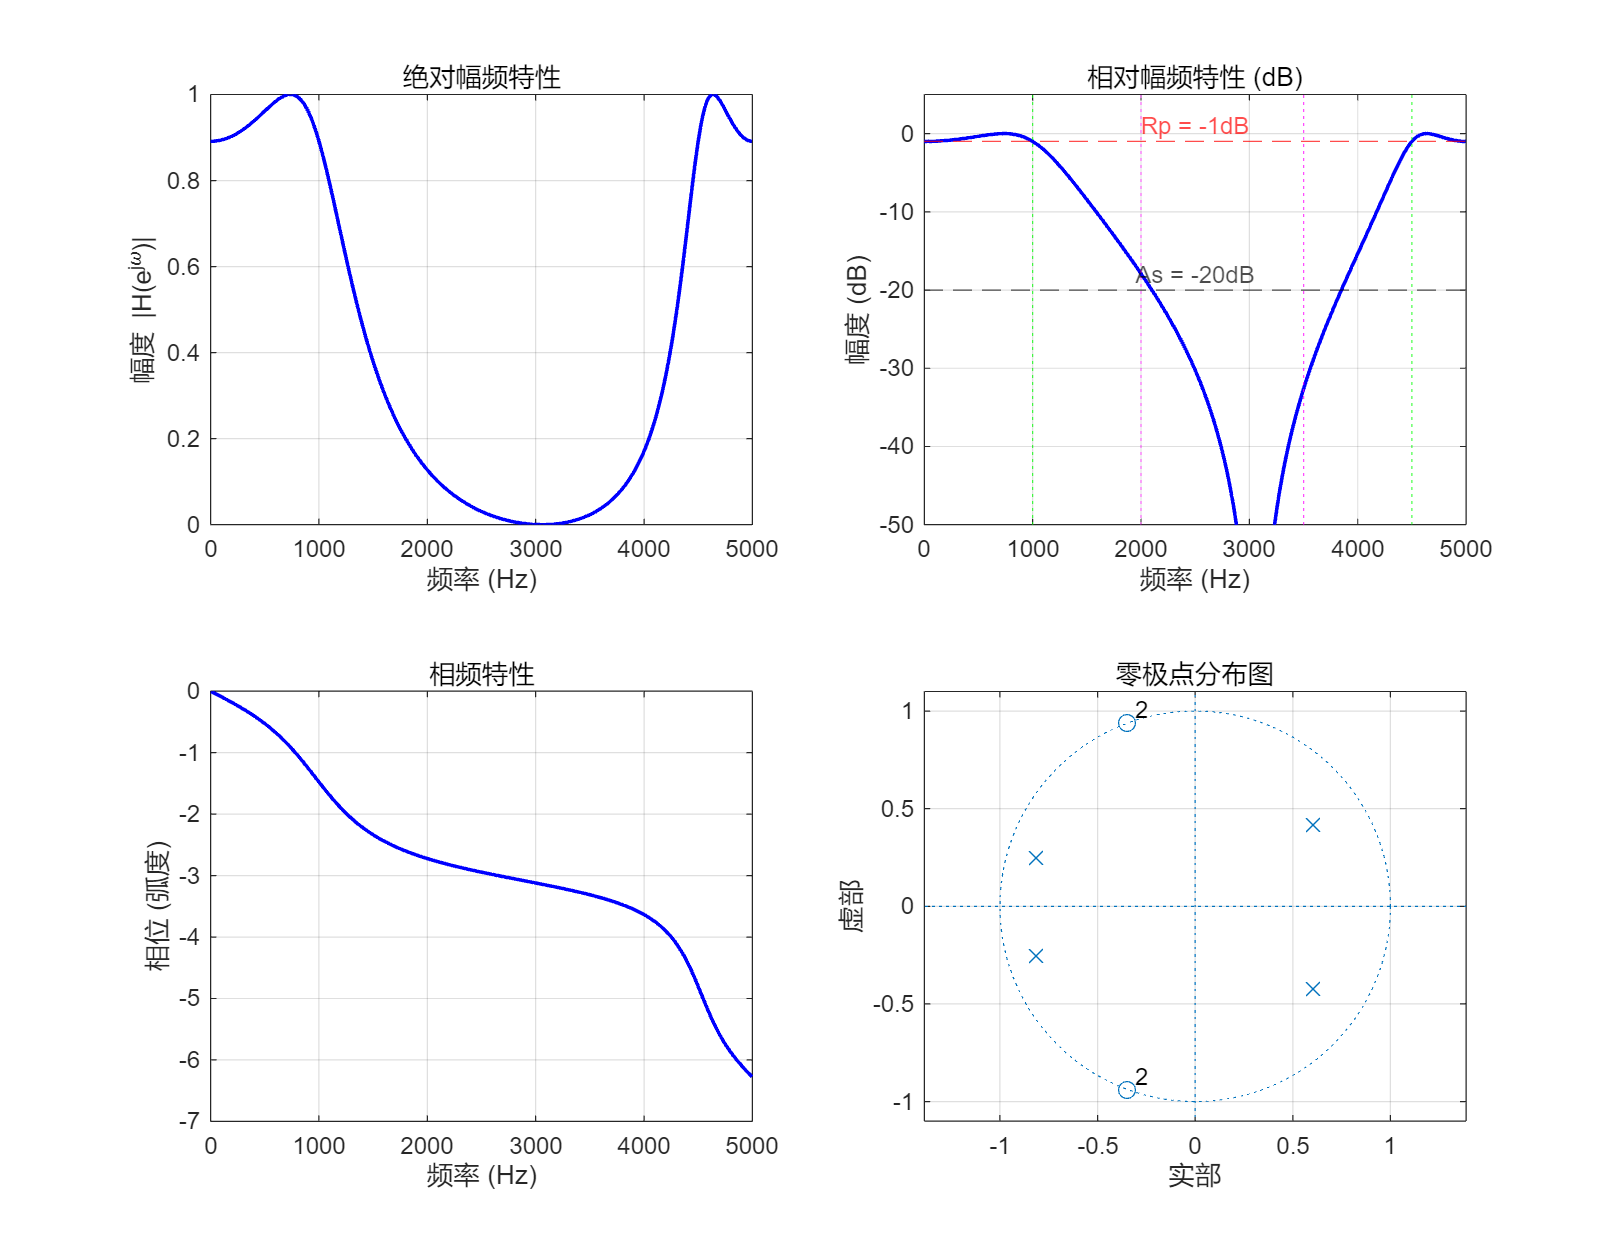

% Insert your code here
clear; clc;

fp1 = 1000;   fp2 = 4500;  
fs1 = 2000;   fs2 = 3500;   
Rp = 1;                   
As = 20;                 
Fs = 10000;

Fn = Fs / 2;
Wp = [fp1, fp2] / Fn;       
Ws = [fs1, fs2] / Fn;

[N, Wn] = cheb1ord(Wp, Ws, Rp, As);
[b, a] = cheby1(N, Rp, Wn, 'stop');

figure('Name', '切比雪夫I型数字带阻滤波器', 'Position', [150, 100, 900, 700]);
[H, f] = freqz(b, a, 1024, Fs);
% (1) 绝对幅频特性
subplot(2, 2, 1);
plot(f, abs(H), 'LineWidth', 1.5, 'Color', 'b');
title('绝对幅频特性');
xlabel('频率 (Hz)'); 
ylabel('幅度 |H(e^{j\omega})|');
grid on;

% (2) 相对幅频特性 (dB)
subplot(2, 2, 2);
mag_dB = 20 * log10(abs(H)); % 切比雪夫I型通带最大值本身即为1(0dB)
plot(f, mag_dB, 'LineWidth', 1.5, 'Color', 'b');
ylim([-50 5]);
yline(-Rp, 'r--', 'Rp = -1dB', 'LabelHorizontalAlignment', 'center');
yline(-As, 'k--', 'As = -20dB', 'LabelHorizontalAlignment', 'center');
xline(fp1, 'g:'); xline(fp2, 'g:');
xline(fs1, 'm:'); xline(fs2, 'm:');
title('相对幅频特性 (dB)');
xlabel('频率 (Hz)'); 
ylabel('幅度 (dB)');
grid on;

% (3) 相频特性 (展开相位避免跳变)
subplot(2, 2, 3);
plot(f, unwrap(angle(H)), 'LineWidth', 1.5, 'Color', 'b');
title('相频特性');
xlabel('频率 (Hz)'); 
ylabel('相位 (弧度)');
grid on;

% (4) 零极点分布图
subplot(2, 2, 4);
zplane(b, a);
title('零极点分布图');
grid on;

### **系统传递函数：**$H(z)=\frac{b_0+b_1z^{-1}+b_2z^{-2}+b_3z^{-3}+b_4z^{-4}}{a_0+a_1z^{-1}-a_2z^{-2}+a_3z^{-3}+a_4z^{-4}}$

**计算出本题系统传递函数为：**$H(z) = \frac{0.13823 + 0.19052 z^{-1} + 0.34210 z^{-2} + 0.19052 z^{-3} + 0.13823 z^{-4}}{1 + 0.42262 z^{-1} - 0.69985 z^{-2} + 0.004905 z^{-3} + 0.39387 z^{-4}}$

### **题目5**`：`***采用脉冲响应不变法设计一个巴特沃斯数字带通滤波器******，*****要求：**

### 通带$w_{p1}=0.3\pi ,w_{p2}=0.7\pi ,R_p=1dB;$阻带$w_{s1}=0.1\pi ,w_{s2}=0.9\pi ,A_s=15dB;$滤波器采样频率$F_s=2000Hz$。试显示数字滤波器的幅频特性和零极点分布图，并写出该系统的传递函数。

**解答5**：

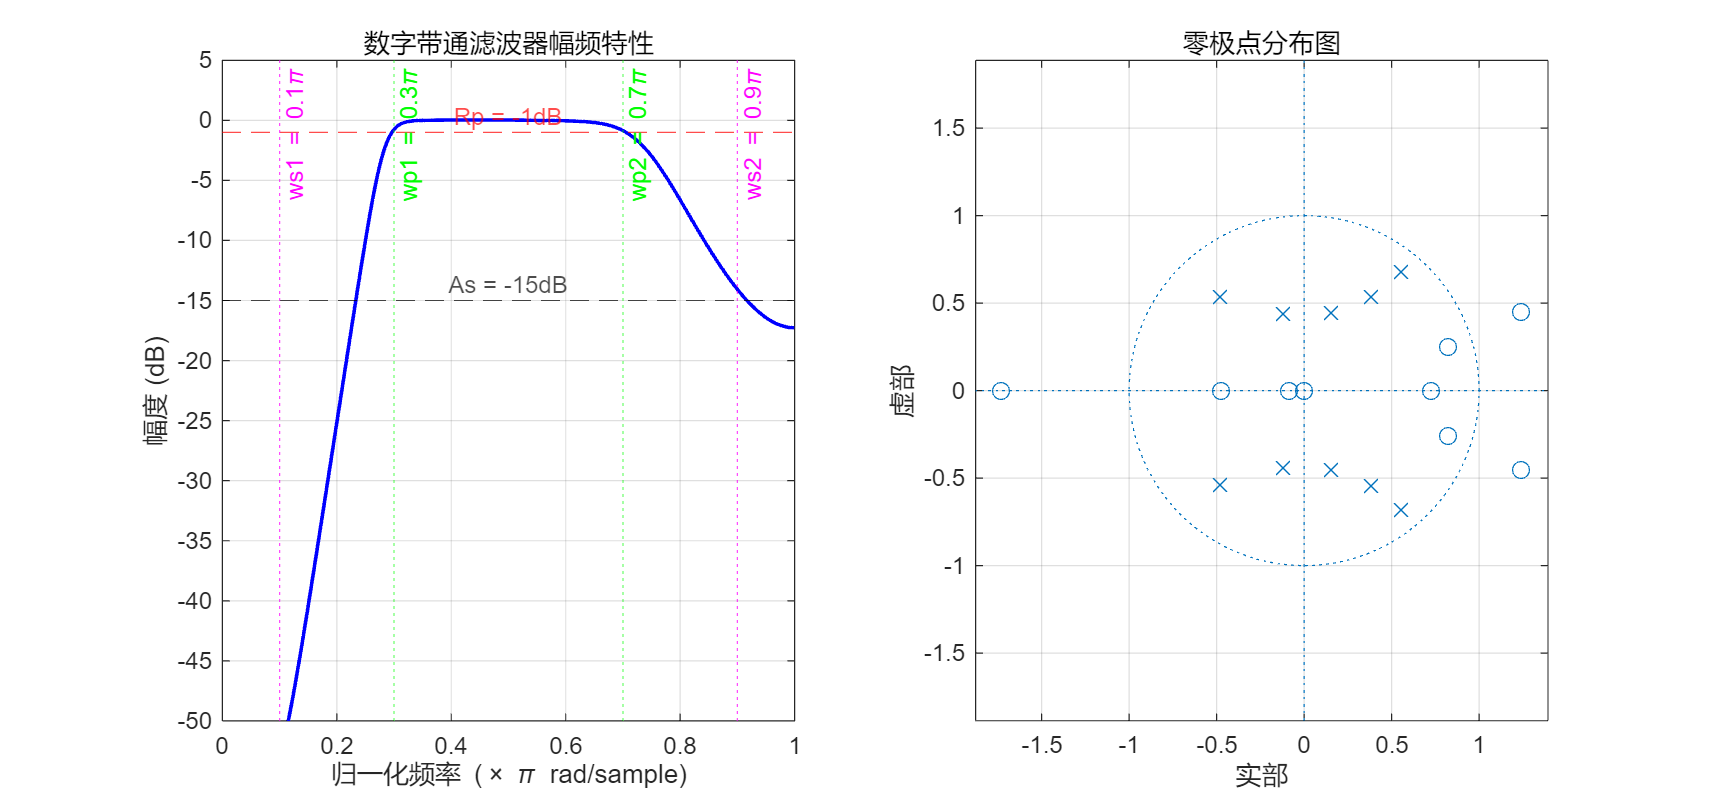

% Insert your code here
clear; clc;
wp = [0.3*pi, 0.7*pi];  
ws = [0.1*pi, 0.9*pi];
Rp = 1;
As = 15;
Fs = 2000;
T = 1 / Fs;

Op = wp / T;
Os = ws / T;

[N, Wn] = buttord(Op, Os, Rp, As, 's');

% 设计模拟巴特沃斯滤波器
[B_s, A_s] = butter(N, Wn, 's');

% 模拟滤波器转换数字滤波器，用脉冲响应不变法
[b_z, a_z] = impinvar(B_s, A_s, Fs);

figure('Name', '脉冲响应不变法 - 带通滤波器设计', 'Position', [150, 150, 950, 450]);

% (1) 幅频特性
subplot(1, 2, 1);
[H, w] = freqz(b_z, a_z, 1024);
mag_dB = 20 * log10(abs(H));

plot(w/pi, mag_dB, 'b', 'LineWidth', 1.5); hold on;
yline(-Rp, 'r--', 'Rp = -1dB', 'LabelHorizontalAlignment', 'center');
yline(-As, 'k--', 'As = -15dB', 'LabelHorizontalAlignment', 'center');
xline(0.3, 'g:', 'wp1 = 0.3\pi'); 
xline(0.7, 'g:', 'wp2 = 0.7\pi');
xline(0.1, 'm:', 'ws1 = 0.1\pi'); 
xline(0.9, 'm:', 'ws2 = 0.9\pi');

ylim([-50, 5]);
title('数字带通滤波器幅频特性');
xlabel('归一化频率 (\times \pi rad/sample)');
ylabel('幅度 (dB)');
grid on;

b_z(abs(b_z) < 1e-6) = 0;

% (2) 零极点分布图
subplot(1, 2, 2);
zplane(b_z, a_z);
title('零极点分布图');
grid on;

**传递函数为：**$H(z) = \frac{0.0678 z^{-1} - 0.1747 z^{-2} - 0.0342 z^{-3} + 0.5150 z^{-4} - 0.5251 z^{-5} + 0.0696 z^{-6} + 0.1299 z^{-7} - 0.0419 z^{-8} - 0.0043 z^{-9}}{1 - 1.0114 z^{-1} + 1.2227 z^{-2} - 0.4894 z^{-3} + 0.7180 z^{-4} - 0.3453 z^{-5} + 0.3649 z^{-6} - 0.1065 z^{-7} + 0.0828 z^{-8} - 0.0130 z^{-9} + 0.0081 z^{-10}}$